# Lab 6 - Varsha Singh

## U50072781

### DTMT Decoding steps

1. Divide the time signal into short time segments representing individual key presses

2. Filter the individual segments to extract the possible frequency components. Bandpass filters can be used to isolate the sinusoidal components.

3. Determine which two frequency components are present in each time segment by measuring the size of the output signal from all of the bandpass filters.

4. Decode which key was pressed, 0-9, *, or # by converting frequency pairs back into row and column indices and thus key names according to Figure 1. 

#### 5.1

Simple Bandpass Filter Design

h(t) = B*cos(2*pi, f_c*t) for o <= t <= Tf

fc - center frequency of a filter (Hz), location of passband

Tf duration in seconds

B adjustable gain

### (A) find and sketch magnitudes of CTFT of g(t) and w(t)

This part is done by hand and included with my pdf submission

### (B) verify results of part (a) with MATLAB

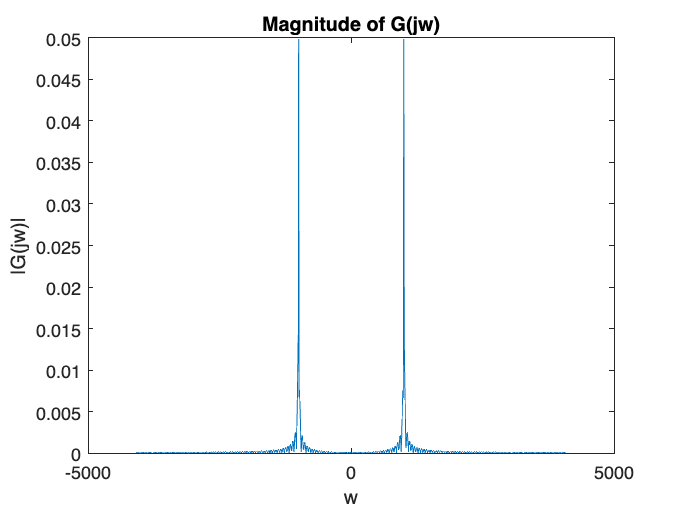

Fs = 8192;
fc = 1000;
Tf = 0.01;
t = 0:1/Fs:0.1;
B = 1;
g = B*cos(2*pi*fc*t);
w = (t<Tf);
h = w.*g;

% use ctft to produce FT of signals at 1000 equally spaced points betwren
% -Fs/2 and Fs/2 HZ

[G,f] = ctft(g,Fs,1000);
[W,f] = ctft(w,Fs,1000);
[H,f] = ctft(h,Fs,1000);

figure(1)
plot(f,abs(G))
xlabel('w')
ylabel('|G(jw)|')
title('Magnitude of G(jw)')

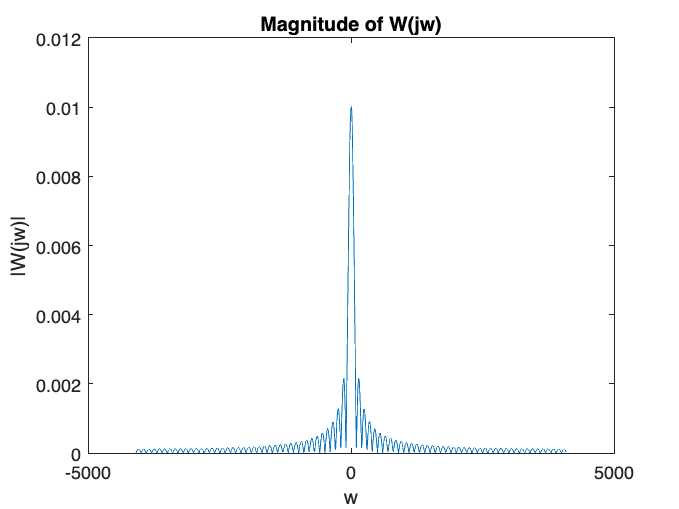


figure(2)
plot(f,abs(W))
xlabel('w')
ylabel('|W(jw)|')
title('Magnitude of W(jw)')

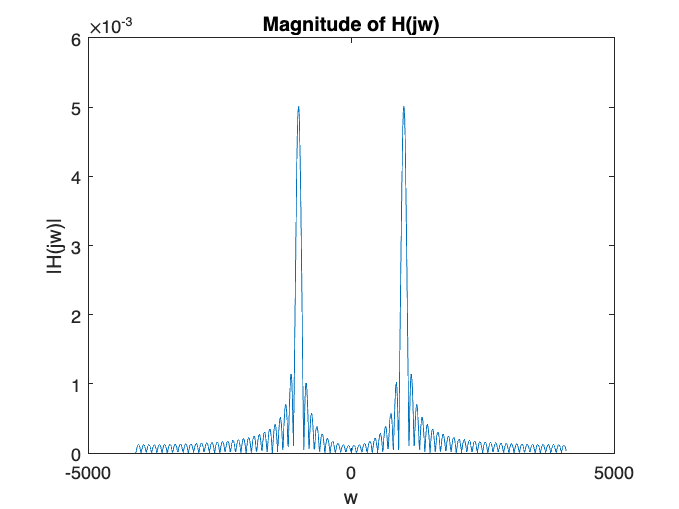


figure(3)
plot(f,abs(H))
xlabel('w')
ylabel('|H(jw)|')
title('Magnitude of H(jw)')

### (c)

#### (c1) create bandpass filter with dtmffilters of window durations and plot their magnitudes using 10,000 sample points

Tf = [0.005, 0.008, 0.02, 0.05] % sec

Tf =     0.0050    0.0080    0.0200    0.0500


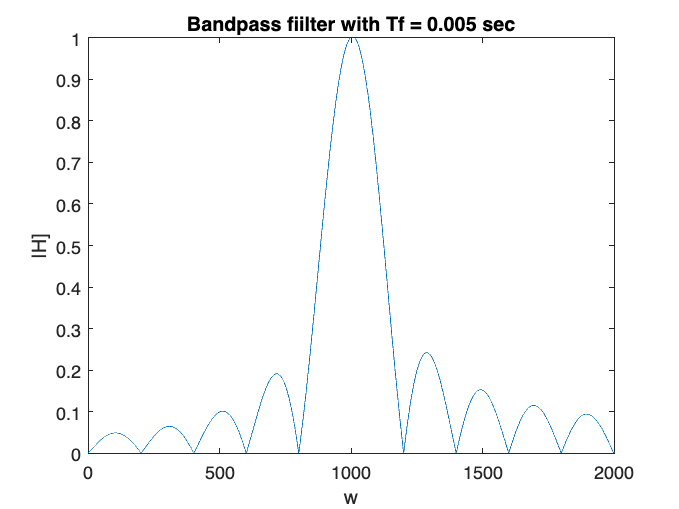

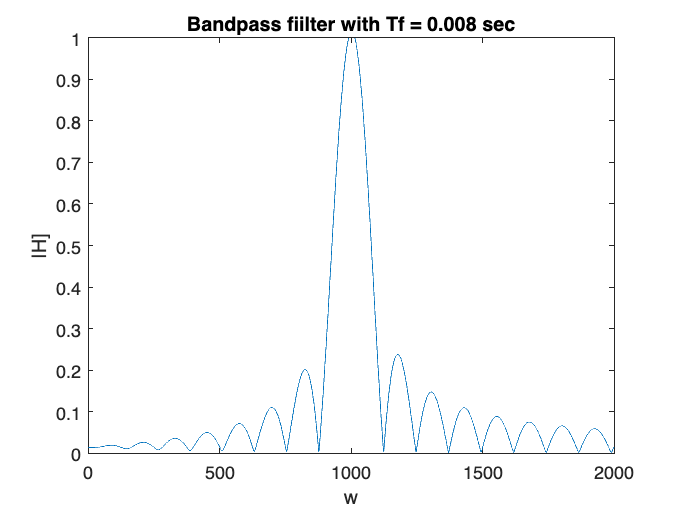

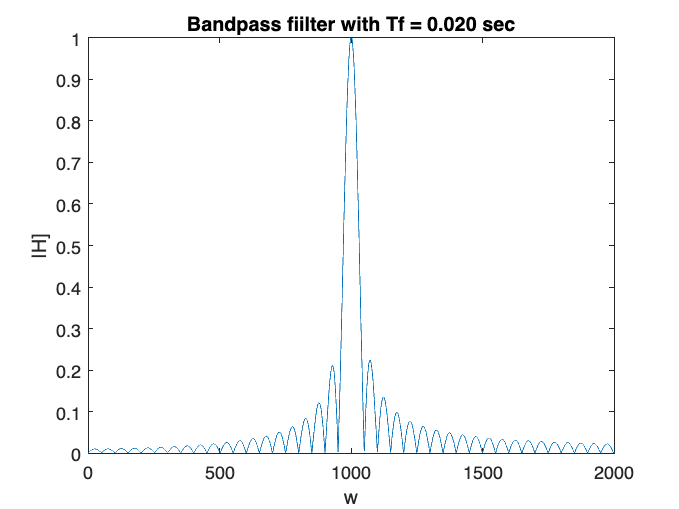

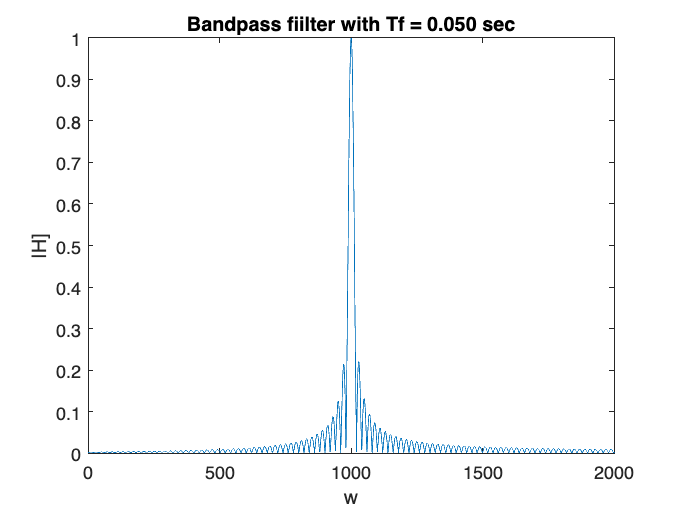

% passband defined by region of frequency response mag close to maximum
% value
% width is length o
% f frequency region, |H(jw| > 1/sqrt(2) * Hmax =
% 0.707*Hmax
fc = 1000;
Fs = 8192;
for i=1:length(Tf)
    h = dtmffilters(fc, Tf(i), Fs);
    [H, f] = ctft(h, Fs, 10000);

    figure(i)
    plot(f, abs(H));
    axis([0 2000 0 1])
    xlabel('w');
    ylabel('|H]');
    titlestr = sprintf('Bandpass fiilter with Tf = %.3f sec', Tf(i));
    title(titlestr)
end

#### (c2): Explain how the pass and stop bands depend on Tf

As Tf grows, we find that the pass band becomes more narrow. As Tf goes to zero, the pass band is wider, meaning that more frequencies are allowed to pass through.

For the stop band: as Tf grows, it becomes more sharply defined, meaning that there is a better separatioon between the pass and stop bands. As Tf goes to zero, the length of the stop band seems to have less attenuation which will reduce the effectiveness of the stop band since it cannot block unwanted frequencies as well.

### (D) Implement 7 bandpass filters for decoding DTMF, each have center frequency at one of the 7 key tones

% Vector of Nf center frequencies of the filter passbands in Hertz
center_freq_hz = [697, 770, 852, 941, 1209, 1336, 1477];
% hAll matrix of all the bandpass filter impulse responses
% Column k contains the bandpass filter impulse response corresponding to
% center frequency center_freq_hz(k). Thus hAll is (Tfilter/Fs) x (Nf)
% matrix

% find the smallest difference
smalldiff = 1500;
for i=1:length(center_freq_hz)-1
    if(smalldiff > center_freq_hz(i+1) - center_freq_hz(i))
        smalldiff = center_freq_hz(i+1) - center_freq_hz(i);
    end
end

fprintf("smallest difference is %d", smalldiff)

smallest difference is 73

l is: 1

 in loop l is: 1

 in loop i isL 1

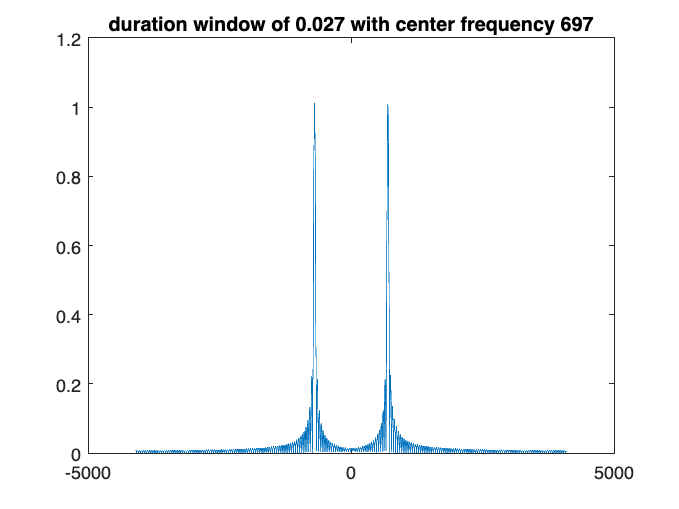

 in loop l is: 1

 in loop i isL 2

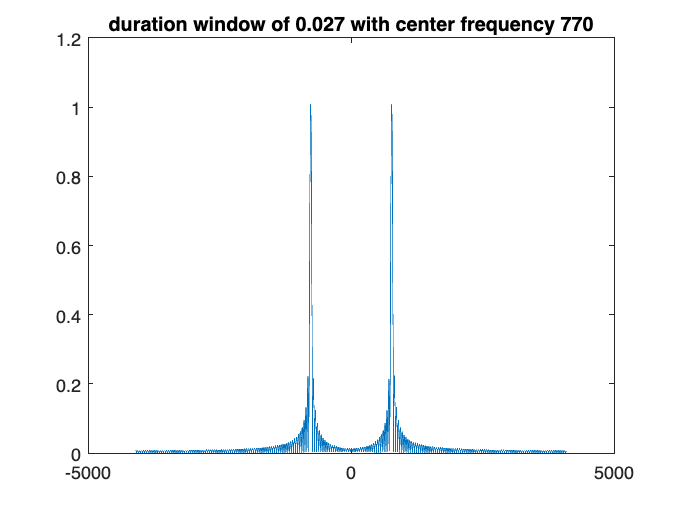

 in loop l is: 1

 in loop i isL 3

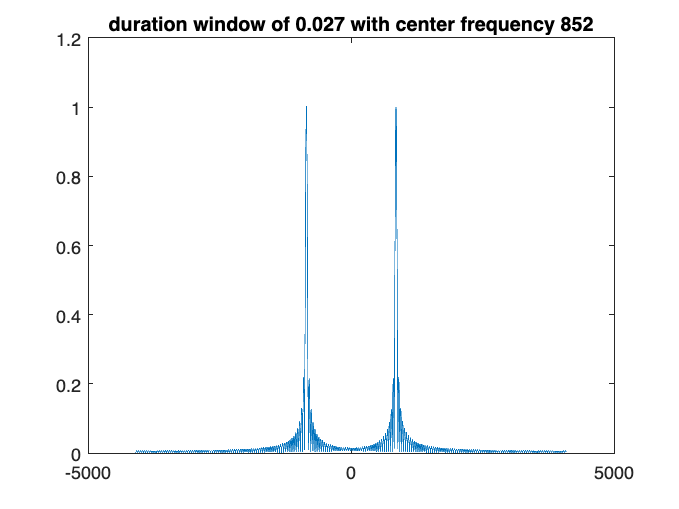

 in loop l is: 1

 in loop i isL 4

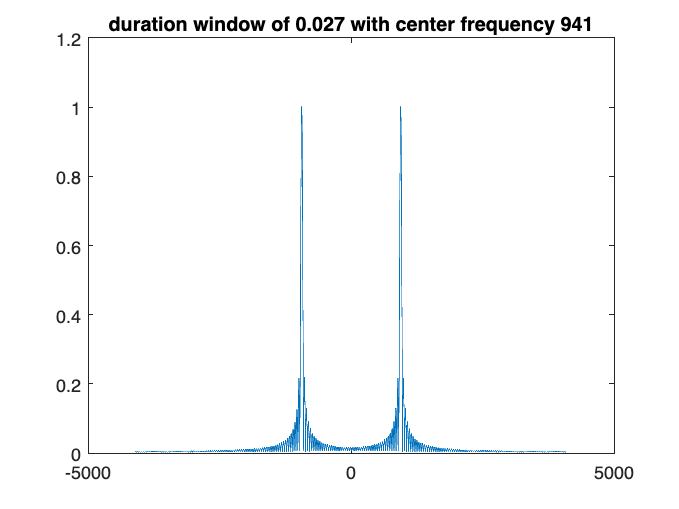

 in loop l is: 1

 in loop i isL 5

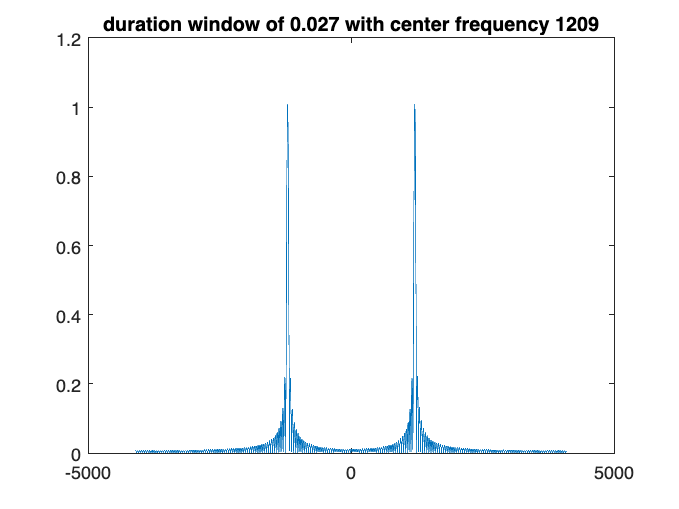

 in loop l is: 1

 in loop i isL 6

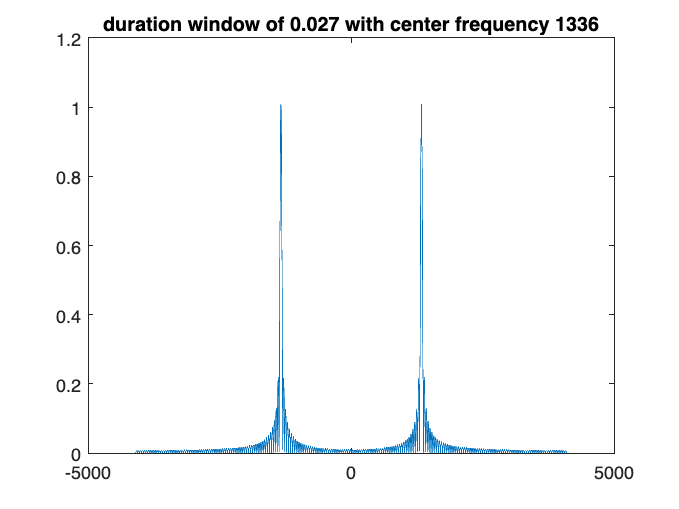

 in loop l is: 1

 in loop i isL 7

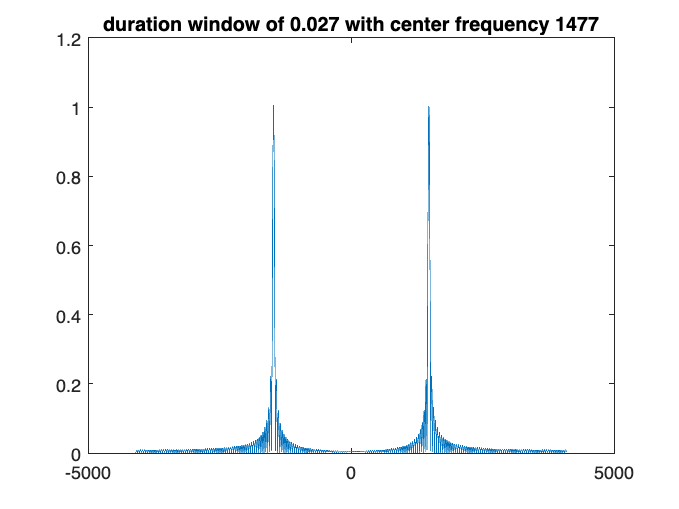

% minimum Tf in order to avoid spectral overlap:
Tf = 2/smalldiff;

figurenum = 1;
Tf_guess = Tf;
for l= 1:length(Tf)
    fprintf('l is: %d', l)
    hAll = dtmffilters(center_freq_hz, Tf, Fs);
    hAll = hAll'; % row-wise
    for i = 1:size(hAll, 1)
        fprintf(' in loop l is: %d', l)
        fprintf(' in loop i isL %d', i)
        [H, f] = ctft(hAll(i, :), Fs, 10000);
        figure(figurenum)
        figurenum = figurenum + 1;
        plot(f, abs(H));
        titlestr = sprintf("duration window of %.3f with center frequency %d", Tf, center_freq_hz(i));
        title(titlestr);
    end
end

#### (d1) Explain how you have chosen value for Tf (find a value of Tf so that only one of the DTMF frequencies lies within the passband of each filter and all other DTFT frequencies lie in the stopband).

I found the value for the Tf by finding the smallest difference in frequencies (Hz) between the different dial tones, and then finding the 2 times the inverse, (2/73) as time and frequency are inversely related. The filter will only pass one component while rejecting the others because the pass band is tight and the region of overlap between the frequency overlap cannot result in noise in the stop band being raised enough to be passed through.

## 5.2

### Creating and Testing a Complete DTMF Decoding System

dtmfkeys - main program. extracts individual key segments from overall signal by calling dtmfcut.m, decoding the individual key segments by calling dtmfdecode, which produced the corresponding keypad row and column pairs for each segment. dtmfdecode calls dtmfdetect repeatedly to perform bandpass filtering.

dtmfdetect filters a given key segment with a given bandpass filter, deterinds the energy in the output, and then thresholds this energy to produce a binary decision of whether significnt energy is present in the associated

dtmfkeys - translates the individual key row and column outputs into corresponding key symbols

#### (a)

% use dtmfdial.m to create some single-key signals containing tone pairs
Key1 = '1';                 % input key sequence
Key2 = '2';                 % input key sequence
Key3 = '3';                 % input key sequence
Key4 = '4';                 % input key sequence
Key5 = '5';                 % input key sequence
Key6 = '6';                 % input key sequence
Key7 = '7';                 % input key sequence
Key8 = '8';                 % input key sequence
Key9 = '9';                 % input key sequence
Key0 = '0';                 % input key sequence
Fs = 8192;                  % sample rate
%Ttone = 0.03;              % out of bounds
%Ttone = 0.05;              % out of bounds
%Ttone = 0.099;             % in bounds
Ttone = 0.1;                % in bounds
%Ttone = 0.5;               % in bounds
%Ttone = 1;                 % in bounds
%Ttone = 5;                 % in bounds


% returns a time domain signal corresponding to key sequence in string Key#
Keys1 = dtmfdial(Key1, Ttone, Fs);
Keys2 = dtmfdial(Key2, Ttone, Fs);
Keys3 = dtmfdial(Key3, Ttone, Fs);
Keys4 = dtmfdial(Key4, Ttone, Fs);
Keys5 = dtmfdial(Key5, Ttone, Fs);
Keys6 = dtmfdial(Key6, Ttone, Fs);
Keys7 = dtmfdial(Key7, Ttone, Fs);
Keys8 = dtmfdial(Key8, Ttone, Fs);
Keys9 = dtmfdial(Key9, Ttone, Fs);
Keys0 = dtmfdial(Key0, Ttone, Fs);
sound(Keys1, Fs)

allKeys = [Keys1; Keys2; Keys3; Keys4; Keys5; Keys6; Keys7; Keys8; Keys9; Keys0];
% stmfdetect to apply filter to single key signals
for i = 1:10
    for j=1:7
        [score, E] = dtmfdetect(allKeys(i,:), hAll(j, :), Fs);
        if score == 1
            fprintf("key %d contains frequency %d\n", i, center_freq_hz(j))
        end
    end
    fprintf("\n")
end

key 1 contains frequency 697
key 1 contains frequency 1209
key 2 contains frequency 697
key 2 contains frequency 1336
key 3 contains frequency 697
key 3 contains frequency 1477
key 4 contains frequency 770
key 4 contains frequency 1209
key 5 contains frequency 770
key 5 contains frequency 1336
key 6 contains frequency 770
key 6 contains frequency 1477
key 7 contains frequency 852
key 7 contains frequency 1209
key 8 contains frequency 852
key 8 contains frequency 1336
key 9 contains frequency 852
key 9 contains frequency 1477
key 10 contains frequency 941
key 10 contains frequency 1336


Implement a complete end-to-end system. DTMF signal with dtmfdial with key sequence

use keytone duration of Ttone = 0.1 seconds and samperate of Fs = 8192

Fs = 8192; % Sample rate
Ttone = 0.1; % Tone duration
KeysIn = '555-1212' % Input key sequence

KeysIn = '555-1212'


sKeys = dtmfdial(KeysIn,Ttone,Fs); % Make DTMF signal
sound(sKeys,Fs) % Play the signal

Tf = 2/73; % Set bandpass filter duration
KeysOut = dtmfkeys(sKeys,Tf,Fs) % Decode the signal back to keys 

KeysOut = '5551212'

Experiment with the decoder

#### (c1) try adding spurious signals and noise

gains = 0.01:0.05:5

gains =     0.0100    0.0600    0.1100    0.1600    0.2100    0.2600    0.3100    0.3600    0.4100    0.4600    0.5100    0.5600    0.6100    0.6600    0.7100    0.7600    0.8100    0.8600    0.9100    0.9600    1.0100    1.0600    1.1100    1.1600    1.2100    1.2600    1.3100    1.3600    1.4100    1.4600    1.5100    1.5600    1.6100    1.6600    1.7100    1.7600    1.8100    1.8600    1.9100    1.9600    2.0100    2.0600    2.1100    2.1600    2.2100    2.2600    2.3100    2.3600    2.4100    2.4600


for i = 1:length(gains)
    gain= gains(i); % set noise gain factor
    noise=gain*(rand(1,length(sKeys))-.5); % normalize noise to have zero mean
    noisyKeys=noise+sKeys; % sum noise and key signal
    fprintf("decode with gain = %.2f", gains(i))
    KeysOut = dtmfkeys(noisyKeys,Tf,Fs) % Decode the signal back to keys
end

decode with gain = 0.01

KeysOut = '5551212'

decode with gain = 0.06

KeysOut = '5551212'

decode with gain = 0.11

KeysOut = '?'

decode with gain = 0.16

KeysOut = '?'

decode with gain = 0.21

KeysOut = '?'

decode with gain = 0.26

KeysOut = '?'

decode with gain = 0.31

KeysOut = '?'

decode with gain = 0.36

KeysOut = '?'

decode with gain = 0.41

KeysOut = '?'

decode with gain = 0.46

KeysOut = '?'

decode with gain = 0.51

KeysOut = '?'

decode with gain = 0.56

KeysOut = '?'

decode with gain = 0.61

KeysOut = '?'

decode with gain = 0.66

KeysOut = '?'

decode with gain = 0.71

KeysOut = '?'

decode with gain = 0.76

KeysOut = '?'

decode with gain = 0.81

KeysOut = '?'

decode with gain = 0.86

KeysOut = '?'

decode with gain = 0.91

KeysOut = '?'

decode with gain = 0.96

KeysOut = '?'

decode with gain = 1.01

KeysOut = '?'

decode with gain = 1.06

KeysOut = '?'

decode with gain = 1.11

KeysOut = '?'

decode with gain = 1.16

KeysOut = '?'

decode with gain = 1.21

KeysOut = '?'

decode with gain = 1.26

KeysOut = '?'

decode with gain = 1.31

KeysOut = '?'

decode with gain = 1.36

KeysOut = '?'

decode with gain = 1.41

KeysOut = '?'

decode with gain = 1.46

KeysOut = '?'

decode with gain = 1.51

KeysOut = '?'

decode with gain = 1.56

KeysOut = '?'

decode with gain = 1.61

KeysOut = '?'

decode with gain = 1.66

KeysOut = '?'

decode with gain = 1.71

KeysOut = '?'

decode with gain = 1.76

KeysOut = '?'

decode with gain = 1.81

KeysOut = '?'

decode with gain = 1.86

KeysOut = '?'

decode with gain = 1.91

KeysOut = '?'

decode with gain = 1.96

KeysOut = '?'

decode with gain = 2.01

KeysOut = '?'

decode with gain = 2.06

KeysOut = '?'

decode with gain = 2.11

KeysOut = '?'

decode with gain = 2.16

KeysOut = '?'

decode with gain = 2.21

KeysOut = '?'

decode with gain = 2.26

KeysOut = '?'

decode with gain = 2.31

KeysOut = '?'

decode with gain = 2.36

KeysOut = '?'

decode with gain = 2.41

KeysOut = '?'

decode with gain = 2.46

KeysOut = '?'

decode with gain = 2.51

KeysOut = '?'

decode with gain = 2.56

KeysOut = '?'

decode with gain = 2.61

KeysOut = '?'

decode with gain = 2.66

KeysOut = '?'

decode with gain = 2.71

KeysOut = '?'

decode with gain = 2.76

KeysOut = '?'

decode with gain = 2.81

KeysOut = '?'

decode with gain = 2.86

KeysOut = '?'

decode with gain = 2.91

KeysOut = '?'

decode with gain = 2.96

KeysOut = '?'

decode with gain = 3.01

KeysOut = '?'

decode with gain = 3.06

KeysOut = '?'

decode with gain = 3.11

KeysOut = '?'

decode with gain = 3.16

KeysOut = '?'

decode with gain = 3.21

KeysOut = '?'

decode with gain = 3.26

KeysOut = '?'

decode with gain = 3.31

KeysOut = '?'

decode with gain = 3.36

KeysOut = '?'

decode with gain = 3.41

KeysOut = '?'

decode with gain = 3.46

KeysOut = '?'

decode with gain = 3.51

KeysOut = '?'

decode with gain = 3.56

KeysOut = '?'

decode with gain = 3.61

KeysOut = '?'

decode with gain = 3.66

KeysOut = '?'

decode with gain = 3.71

KeysOut = '?'

decode with gain = 3.76

KeysOut = '?'

decode with gain = 3.81

KeysOut = '?'

decode with gain = 3.86

KeysOut = '?'

decode with gain = 3.91

KeysOut = '?'

decode with gain = 3.96

KeysOut = '?'

decode with gain = 4.01

KeysOut = '?'

decode with gain = 4.06

KeysOut = '?'

decode with gain = 4.11

KeysOut = '?'

decode with gain = 4.16

KeysOut = '?'

decode with gain = 4.21

KeysOut = '?'

decode with gain = 4.26

KeysOut = '?'

decode with gain = 4.31

KeysOut = '?'

decode with gain = 4.36

KeysOut = '?'

decode with gain = 4.41

KeysOut = '?'

decode with gain = 4.46

KeysOut = '?'

decode with gain = 4.51

KeysOut = '?'

decode with gain = 4.56

KeysOut = '?'

decode with gain = 4.61

KeysOut = '?'

decode with gain = 4.66

KeysOut = '?'

decode with gain = 4.71

KeysOut = '?'

decode with gain = 4.76

KeysOut = '?'

decode with gain = 4.81

KeysOut = '?'

decode with gain = 4.86

KeysOut = '?'

decode with gain = 4.91

KeysOut = '?'

decode with gain = 4.96

KeysOut = '?'

### (c2) Try shorter bandpass filter durations

Tf = 1/73; % Set bandpass filter duration
KeysOut = dtmfkeys(sKeys,Tf,Fs) % Decode the signal back to keys

KeysOut = '5551212'


Tf = 0.5/73; % Set bandpass filter duration
KeysOut = dtmfkeys(sKeys,Tf,Fs) % Decode the signal back to keys 

KeysOut = '5551212'


Tf = 0.25/73; % Set bandpass filter duration
KeysOut = dtmfkeys(sKeys,Tf,Fs) % Decode the signal back to keys 

KeysOut = '???????'


Tf = 0.125/73; % Set bandpass filter duration
KeysOut = dtmfkeys(sKeys,Tf,Fs) % Decode the signal back to keys 

KeysOut = '???????'

#### (c3) Describe other possibilities for tone detection

Another possibility for tone detection would be to use machine learning, once enough data has been collected. If you can have a model learn about tone characteristics, you can make it such that it does not get influenced by noise. This can also be implemented with Bayesian inference to determine the probability that a detected signal matches a DTMF tone.